addpath Function\
addpath Template_data\ 

# ** Copy your code here:**

addpath Function\
addpath Semester_2nd_data\

x=load("1series_2.txt");
y=load("1series_3.txt");
 
% One-side:  0.95  1-0.05
% Two-side:  u2u("95s")  u2u("5a")
conf=confidence_tool();

[sig1,sig2,e1,e2]=deal(0.0015,0.0015,34,34);
[mean1,s1,f1]=conf.mean_s_dof(x);
[mean2,s2,f2]=conf.mean_s_dof(y);

[a,b]=conf.get_interval_f(u2u("95s"),s1,s2,f1,f2);

The interval boundary is [0.4967,1.552]
The confidence Level = 95.00%, Error probability = 5.00%


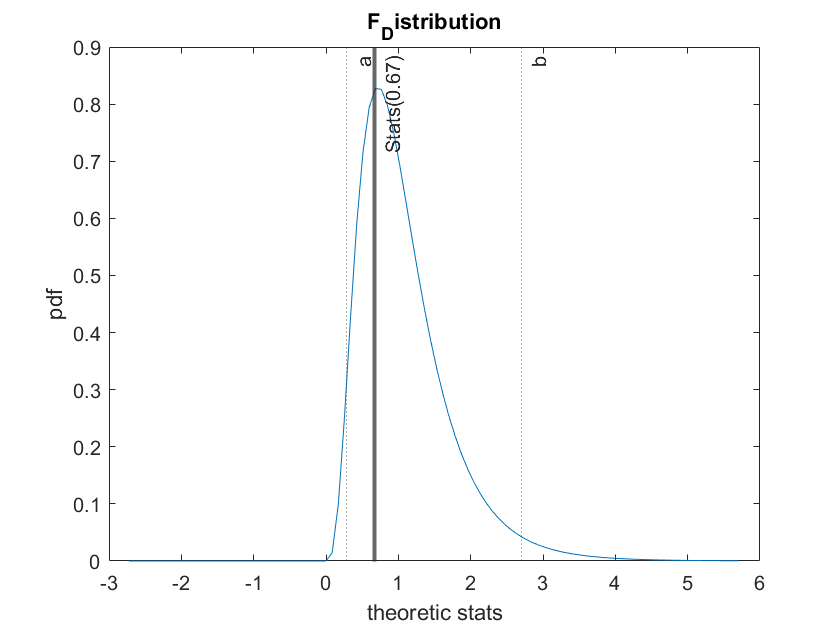

Test Statistic (s2/s1)^2: 0.67 ,Critical value=[0.28,2.70]
Fails to reject the null hypothesis H0


stats=conf.statistic_test_f(u2u("95s"),sig1,sig2,s1,s2,f1,f2);


[a,b]=conf.get_interval_chi(u2u("95s"),s1,f1);

The interval boundary is [0.003133,0.00118]
The confidence Level = 95.00%, Error probability = 5.00%


[a,b]=conf.get_interval_chi(u2u("95s"),s2,f2);

The interval boundary is [0.002924,0.001641]
The confidence Level = 95.00%, Error probability = 5.00%


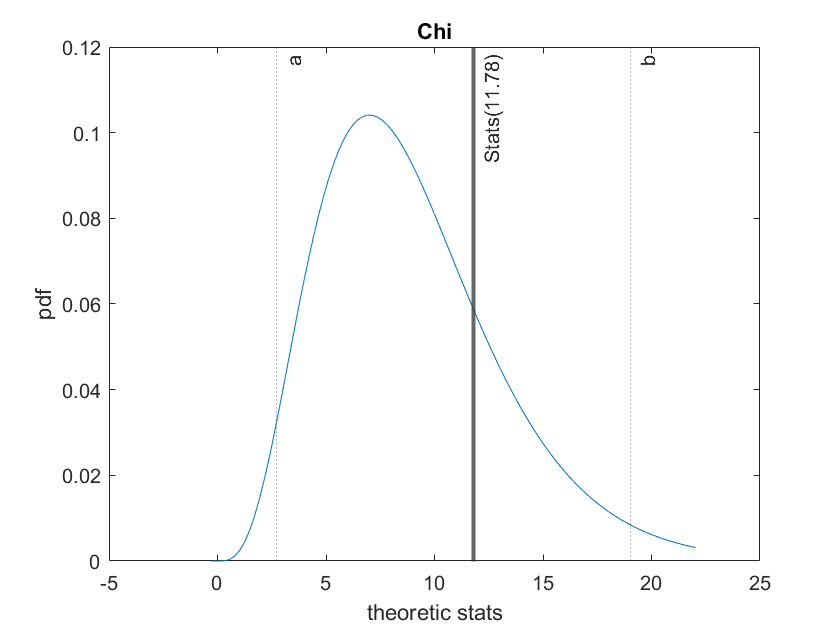

Test Statistic: 11.78 ,Critical value=[2.70,19.02]
Fails to reject the null hypothesis H0


stats=conf.statistic_test_chi(u2u("95s"),sig1, s1,f1);

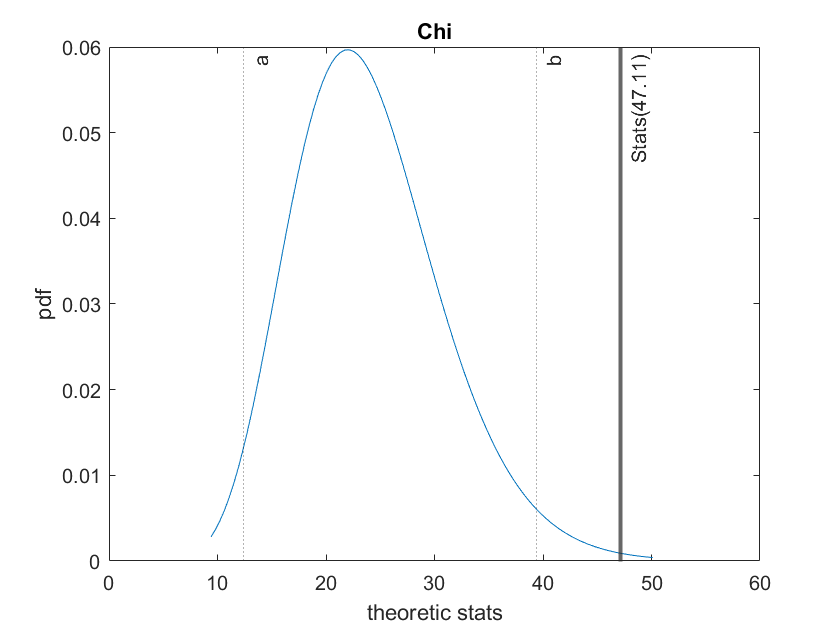

Test Statistic: 47.11 ,Critical value=[12.40,39.36]
1,Reject the null hypothesis H0: Same
1,Reject HC: Significant smaller with S=97.50%
2.Choose hypothesis HA: Significant Bigger with S=97.50%
2.Choose hypothesis HB: Significant difference with S=95.00%


stats=conf.statistic_test_chi(u2u("95s"),sig2, s2,f2);

Task2 Copy this to test.mlx 

addpath Function\
addpath Semester_2nd_data\

x=load("1series.txt");

% One-side:  0.95  1-0.05
% Two-side:  u2u("95s")  u2u("5a")
conf=confidence_tool();

[sig1,e1]=deal(0.0015,34);
[mean1,s1,f1]=conf.mean_s_dof(x);

[a,b]=conf.get_interval_t(u2u("5a"),mean1,s1,f1);

The interval boundary is [50.97,51.03]
The confidence Level = 95.00%, Error probability = 5.00%


[a,b]=conf.get_interval_t(u2u("5a"),mean1,s1,f1);

The interval boundary is [50.97,51.03]
The confidence Level = 95.00%, Error probability = 5.00%


## Exercise 2

Task 1. Copy this to test.mlx

addpath Function\
addpath Semester_2nd_data\

% One-side:  0.95  1-0.05
% Two-side:  u2u("95s")  u2u("5a")
conf=confidence_tool();
[sig1,e1]=deal(1,0);
[mean1,s1,f1]=deal(u2u("3.5mm"),u2u("1.7mm"),9);

[a,b]=conf.get_interval_t(u2u("10a"),mean1,s1,f1);

The interval boundary is [0.0003837,0.006616]
The confidence Level = 90.00%, Error probability = 10.00%


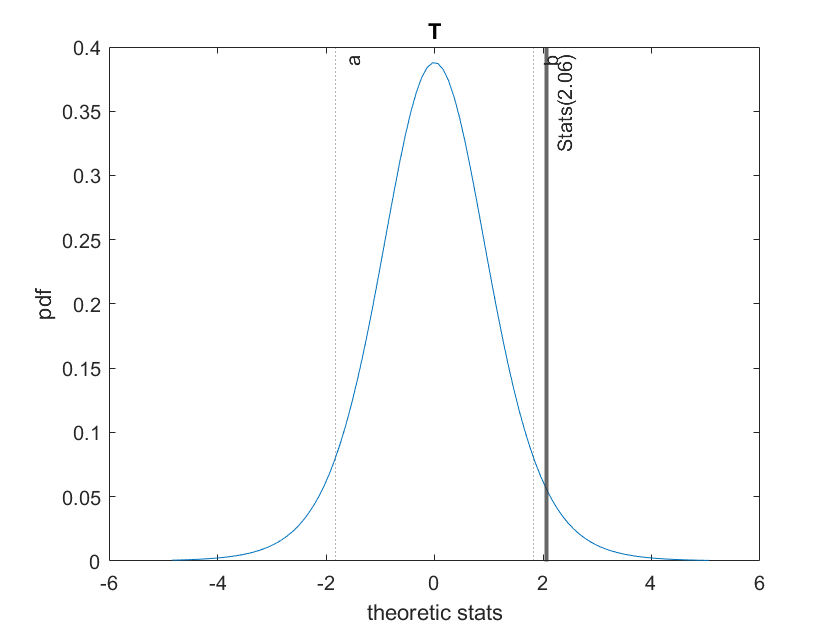

Test Statistic: 2.06 ,Critical value=[-1.83,1.83]
1,Reject the null hypothesis H0: Same
1,Reject HC: Significant smaller with S=95.00%
2.Choose hypothesis HA: Significant Bigger with S=95.00%
2.Choose hypothesis HB: Significant difference with S=90.00%


stats=conf.statistic_test_t(u2u("10a"),e1,mean1,s1,f1);

Task 2  Copy this to test.mlx

addpath Function\
addpath Semester_2nd_data\

% One-side:  0.95  1-0.05
% Two-side:  u2u("95s")  u2u("5a")
conf=confidence_tool();
[sig1,e1]=deal(u2u("2mm"),0);
[mean1,s1,f1]=deal(u2u("3.5mm"),u2u("2.2mm"),9);

[a,b]=conf.get_interval_chi(u2u("5a"),s1,f1);

The interval boundary is [0.004016,0.001513]
The confidence Level = 95.00%, Error probability = 5.00%


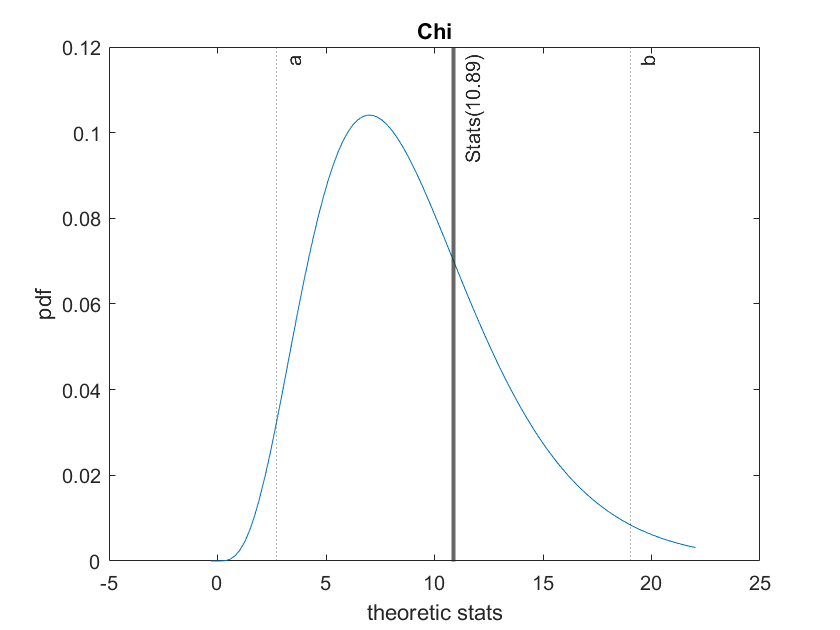

Test Statistic: 10.89 ,Critical value=[2.70,19.02]
Fails to reject the null hypothesis H0


stats=conf.statistic_test_chi(u2u("5a"),sig1, s1,f1);

Task 3  Copy this to test.mlx

addpath Function\
addpath Semester_2nd_data\

% One-side:  0.95  1-0.05
% Two-side:  u2u("95s")  u2u("5a")
conf=confidence_tool();
[sig1,sig2,e1,e2]=deal(0.0015,0.0015,34,34);
[mean1,s1,f1]=deal(0.0015,61,9);
[mean2,s2,f2]=deal(0.0015,54,9);

[a,b]=conf.get_interval_f(0.9,s1,s2,f1,f2);

The interval boundary is [0.7231,1.765]
The confidence Level = 80.00%, Error probability = 20.00%


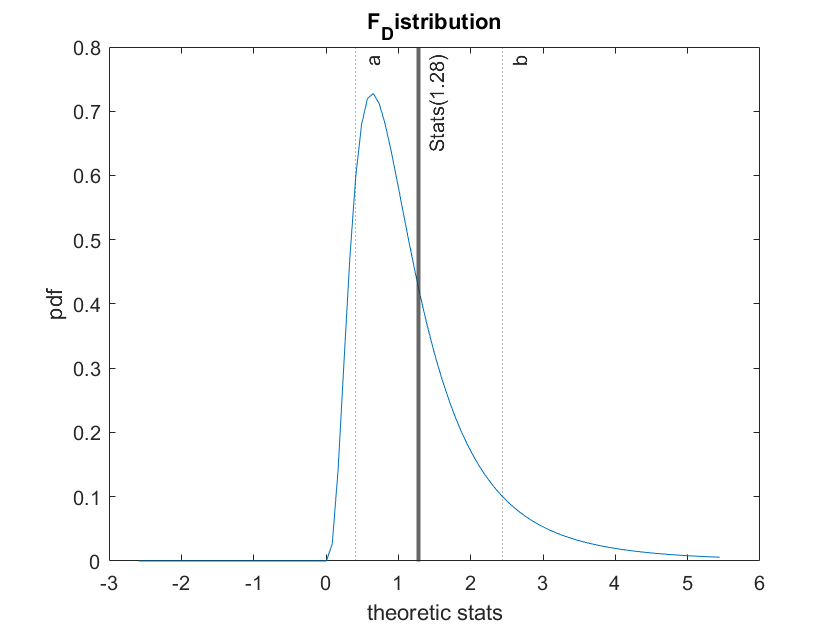

Test Statistic (s2/s1)^2: 1.28 ,Critical value=[0.41,2.44]
Fails to reject the null hypothesis H0


stats=conf.statistic_test_f(0.9,sig1,sig2,s1,s2,f1,f2);

Task 4  Copy this to test.mlx

addpath Function\
addpath Semester_2nd_data\

% One-side:  0.95  1-0.05
% Two-side:  u2u("95s")  u2u("5a")
conf=confidence_tool();
[sig1,e1]=deal(1,6);
[mean1,s1,f1]=deal(u2u("5.5m"),u2u("1m"),15);

[a,b]=conf.get_interval_t(u2u("5a"),mean1,s1,f1);

The interval boundary is [3.369,7.631]
The confidence Level = 95.00%, Error probability = 5.00%


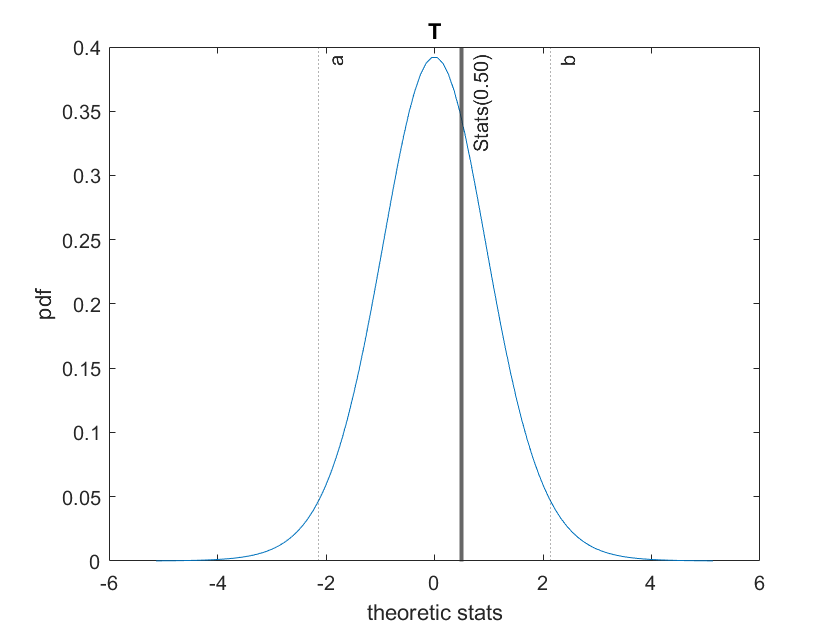

Test Statistic: 0.50 ,Critical value=[-2.13,2.13]
Fails to reject the null hypothesis H0


stats=conf.statistic_test_t(u2u("5a"),e1,mean1,s1,f1);

Task 5  Copy this to test.mlx

addpath Function\
addpath Semester_2nd_data\

% One-side:  0.95  1-0.05
% Two-side:  u2u("95s")  u2u("5a")
conf=confidence_tool();
[sig1,e1]=deal(sqrt(u2u("0.1m")),0);
[mean1,s1,f1]=deal(u2u("3.5mm"),sqrt(u2u("0.07m")),11);

[a,b]=conf.get_interval_chi(u2u("5a"),s1,f1);

The interval boundary is [0.4492,0.1874]
The confidence Level = 95.00%, Error probability = 5.00%


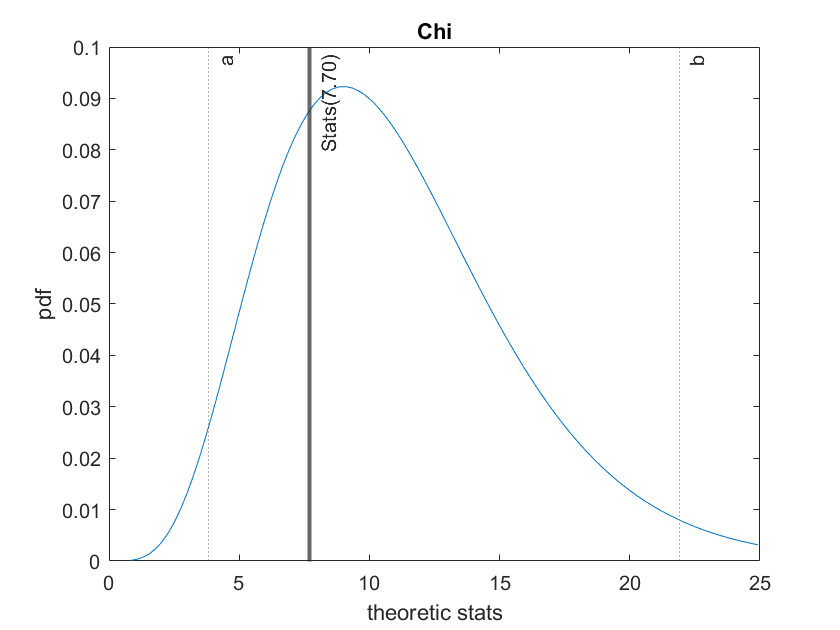

Test Statistic: 7.70 ,Critical value=[3.82,21.92]
Fails to reject the null hypothesis H0


stats=conf.statistic_test_chi(u2u("5a"),sig1, s1,f1);

Task 6  Copy this to test.mlx

addpath Function\
addpath Semester_2nd_data\

% One-side:  0.95  1-0.05
% Two-side:  u2u("95s")  u2u("5a")
conf=confidence_tool();
[sig1,e1]=deal(1,0);
[mean1,s1,f1]=deal(8.73,sqrt(0.35),15);
[mean2,s2,f2]=deal(8.68,sqrt(0.40),17);


[a,b]=conf.get_interval_t(u2u("5a"),abs(mean1-mean2),s1+s2,f1+f2);

The interval boundary is [-2.443,2.543]
The confidence Level = 95.00%, Error probability = 5.00%


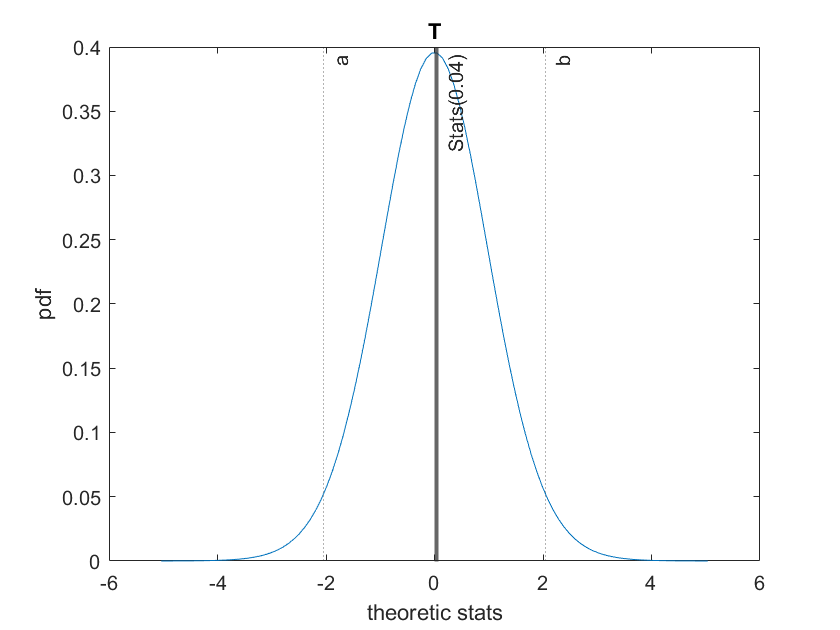

Test Statistic: 0.04 ,Critical value=[-2.04,2.04]
Fails to reject the null hypothesis H0


stats=conf.statistic_test_t(u2u("5a"),mean1,mean2,s1+s2,f1+f2);

# **Note:**

**One Side Problem:**

a=5 s=95 in lecture 

0.95 in matlab function

u2u("10a) u2u("90s) in my code

**Two Side Problem:**

a=5 s=95 in lecture 

0.975 in matlab function

u2u("5a) u2u("95s) in my code